## Import Data

clear all;
clc;
data = readtable("step_osc_150ohm.csv");
data = fillmissing(data,'nearest');
data([1,2],:) = [];

## Assign Variables

% Seperate values
t = table2array(data(:,1))+5;
Vout = table2array(data(:,2));
D = table2array(data(:,3));

% Match to duty cycle
D = round(D/5)*10+50;       

% Find index before step
idx = find(D<60,1,'last');

% Trim data with new index
t = t(idx-9:end);
Vout = Vout(idx-9:end);
D = D(idx-9:end);

% Reset time and find sampling time
t = t-t(1);
T_s=t(2)-t(1)

T_s = 0.0039

## Identify Transfer Functions

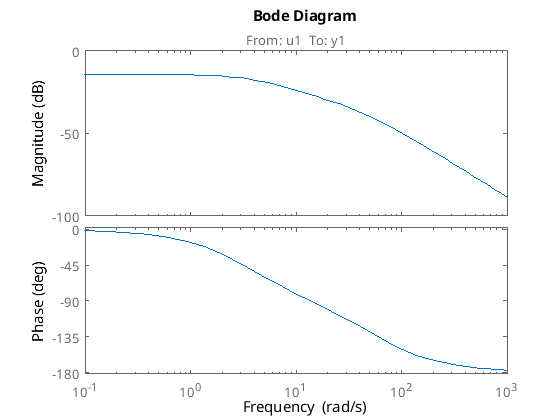

idd = iddata(Vout,D,T_s);
G=tfest(idd,2,0);
bode(G)

gm = 60; Ni=5; alpha=0.5;
[wc, Kp, taui, taud, ok] = findpid(G,gm,Ni,alpha)

ans = 'Found 1 valid solution(s) out of 1 phase crossing(s)'

wc = 48.1552

Kp = 63.7188

taui = 0.1038

taud = 0.0294

ok = 1

s=tf('s');
Cpid=Kp*(taud*s+1)/(alpha*taud*s+1)*(taui*s+1)/(taui*s)

Cpid =
 
  0.1943 s^2 + 8.487 s + 63.72
  ----------------------------
    0.001525 s^2 + 0.1038 s
 
Continuous-time transfer function.



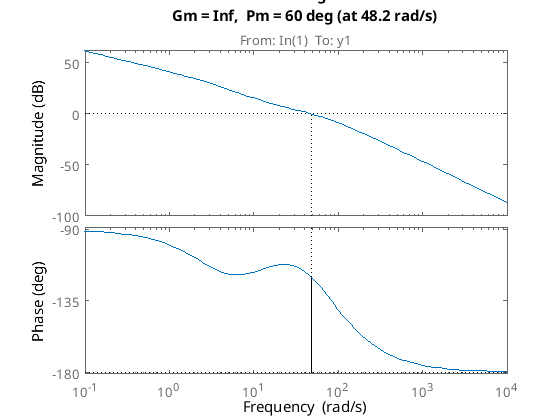

Gol=G*Cpid;
margin(Gol);